Fmax = 5500;
Lopt = 0.055;
Arel = 0.3;
Brel = 3.6;
Fiso = 0.9;
q = 0.5;
Fcc = Fmax*Fiso*q;
fac = min(1, 3.33*q);
F = Fiso*q*Fmax*(0:100)/100;
Vcc = fac*Lopt*Brel*(1-Fmax*q*(Fiso+Arel)./(F+Arel*Fmax*q));
aveP = fac*Lopt*Brel*q*Fmax*Fiso*(1/2+Arel/Fiso-Arel*(Fiso+Arel)*reallog(1+Fiso/Arel)/Fiso^2)

aveP = 106.4401


Vcc_Vcon(1:90) = -aveP*2/(Fmax*q*Fiso*0.9);
Vcc_Vcon(91:101) = interp1([90,100],[-aveP*2,0],90:100)./(Fmax*q*Fiso*(90:100)/100);
aveP_Vcon = mean(-Vcc_Vcon.*F)

aveP_Vcon = 105.3862


Vcc_Pcon(2:10) = -interp1([0,9],[0,aveP*10/9],1:9)./F(2:10);
Vcc_Pcon(1) = Vcc_Pcon(2);
Vcc_Pcon(11:90) = -(aveP*10/9)./F(11:90);
Vcc_Pcon(91:101) = -interp1([90,100],[aveP*10/9,0],90:100)./F(91:101);
P_arr = -Vcc_Pcon.*F;
aveP_Pcon = mean(P_arr(1:101))

aveP_Pcon = 105.9717

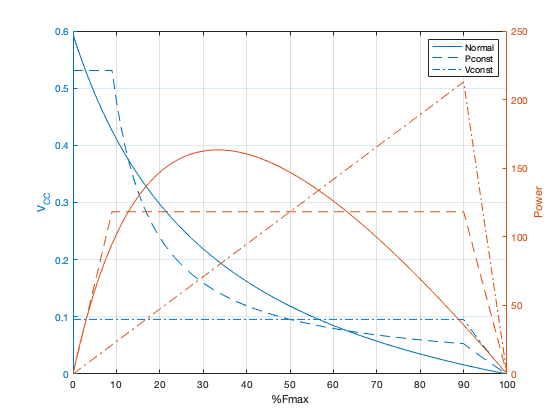


yyaxis left
plot(0:100,-Vcc,'-')
hold on
plot(0:100, -Vcc_Pcon,'--')
plot(0:100, -Vcc_Vcon,'-.')
ylabel('V_{CC}')
yyaxis right
plot(0:100,-Vcc.*F,'-')
hold on
plot(0:100, -Vcc_Pcon.*F,'--')
plot(0:100, -Vcc_Vcon.*F,'-.')
ylabel('Power')
xlabel('%Fmax')
grid on
legend('Normal', 'Pconst', 'Vconst')